## Animal 4619

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_4619\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\4619';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'aligned_stack_with_contours.xml'));
xlTable = readtable(fullfile(animalDir,'aligned_stack_with_contours_contours_23_08_11.xlsx'));

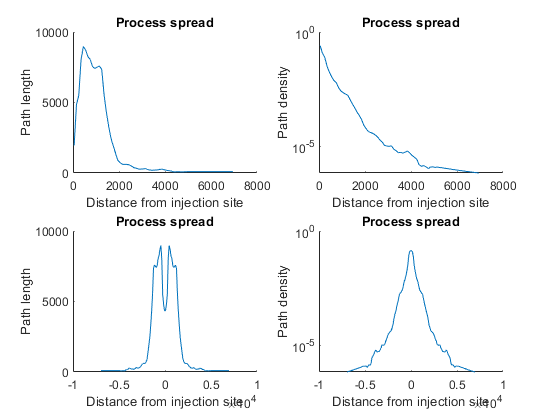

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal4619.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker{2}.point.Attributes, true);

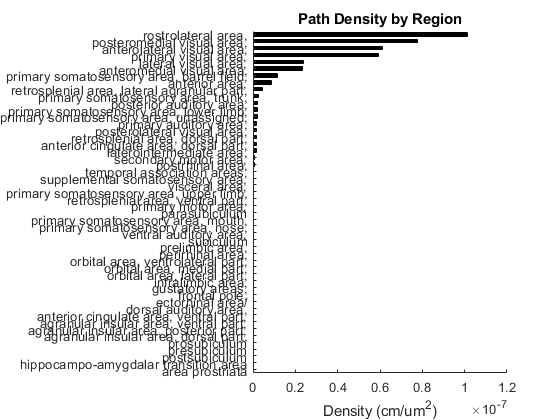

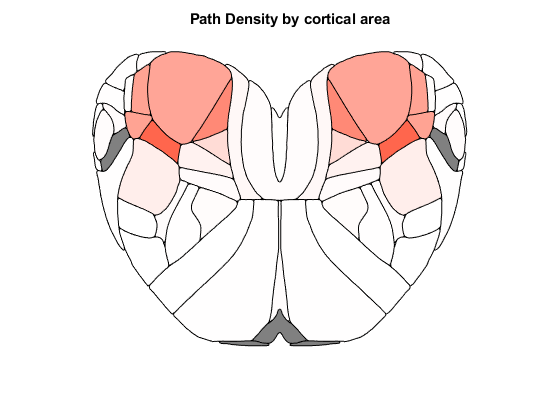

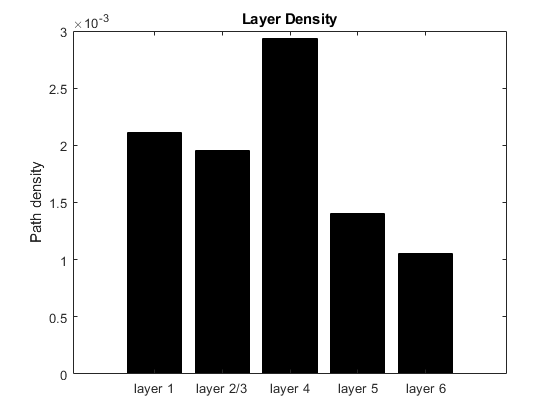

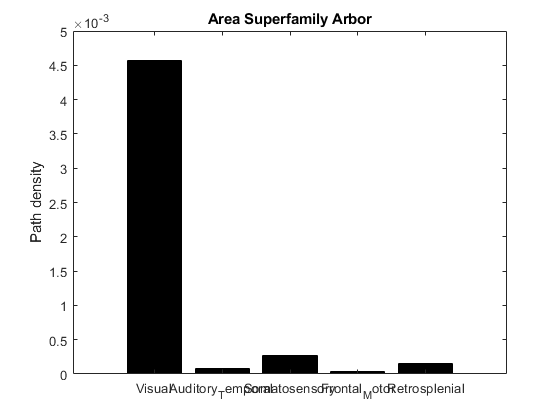

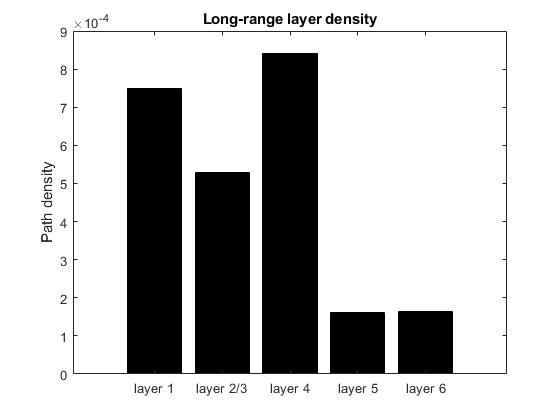


animal4619.tracingTables = buildTracingOutputTables(xmlData, xlTable, true, saveDir);


animal4619.somaCount = length(xmlData.mbf.marker{1}.point);

## Animal 5006

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_5006\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\5006';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'aligned_stack_with_contours.xml'));
xlTable = readtable(fullfile(animalDir,'aligned_stack_with_contours_contours_23_08_11.xlsx'));

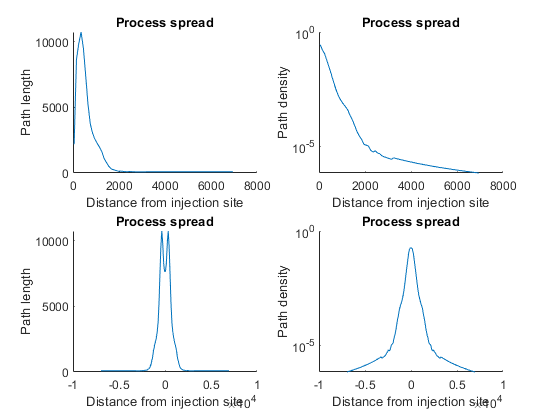

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal5006.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker{2}.point.Attributes, true);

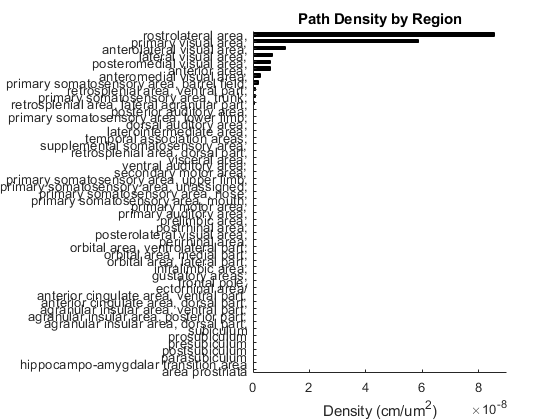

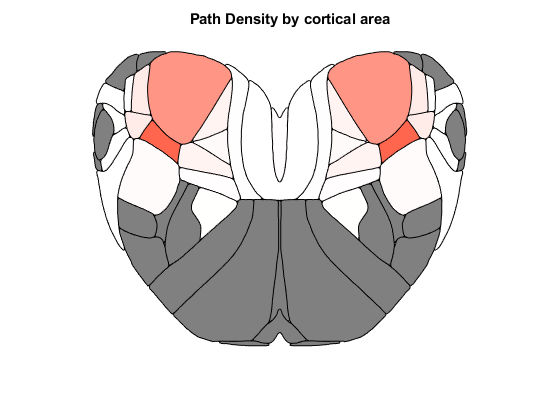

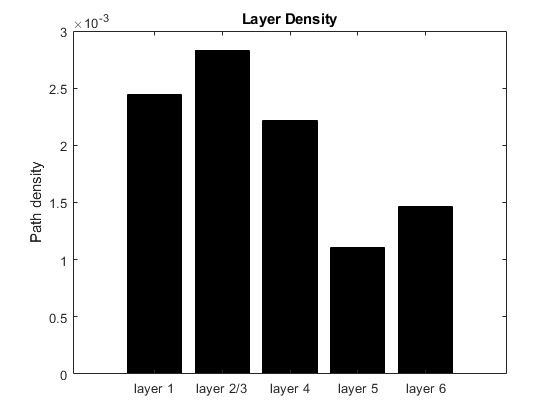

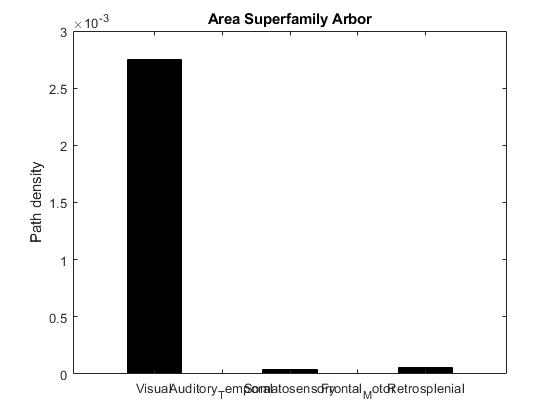

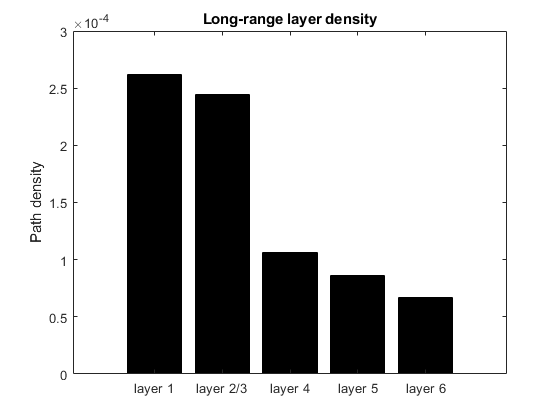


animal5006.tracingTables = buildTracingOutputTables(xmlData, xlTable, true, saveDir);


animal5006.somaCount = length(xmlData.mbf.marker{1}.point);

## Animal 5008

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_5008\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\5008';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'aligned_stack_with_contours_v2.xml'));
xlTable = readtable(fullfile(animalDir,'aligned_stack_with_contours_v2_contours_23_08_11.xlsx'));

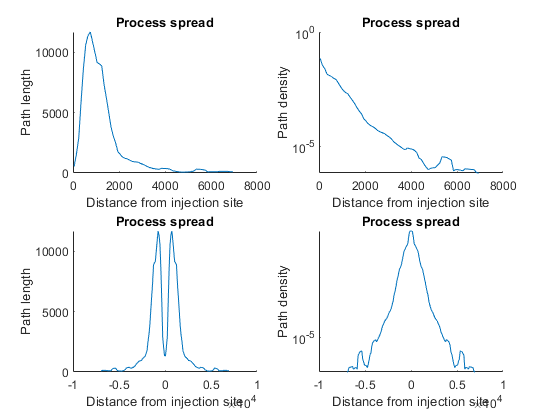

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal5008.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker{2}.point.Attributes, true);

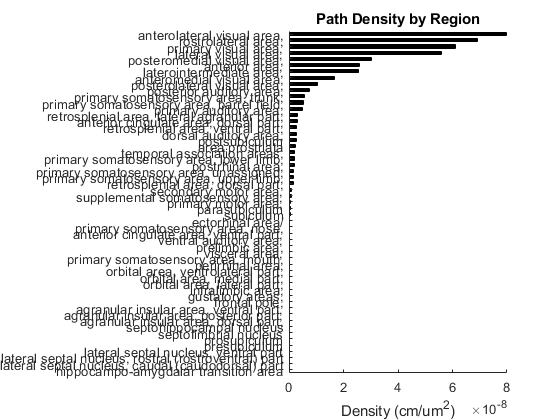

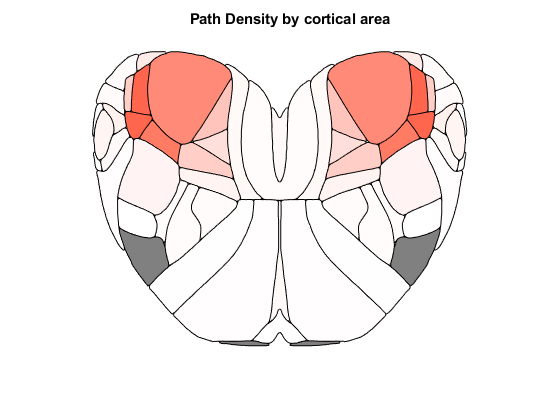

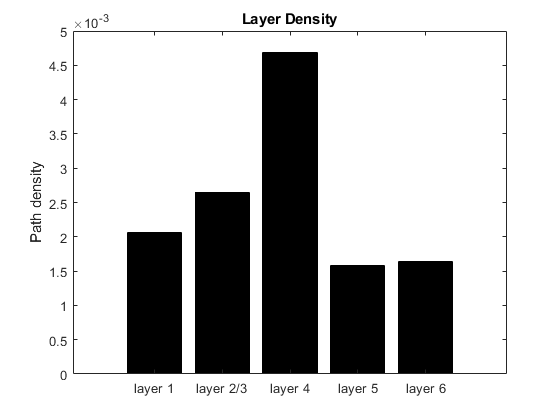

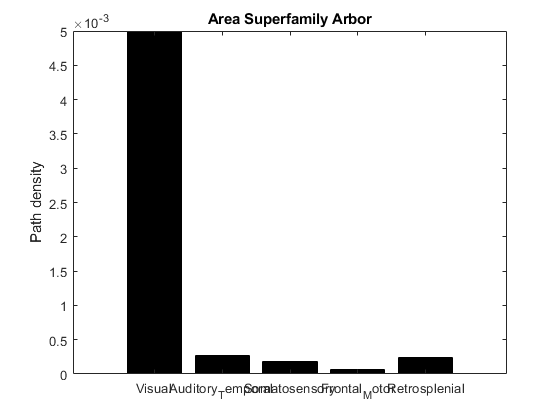

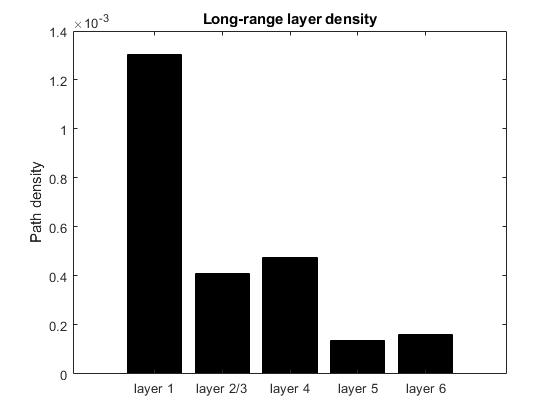


animal5008.tracingTables = buildTracingOutputTables(xmlData, xlTable, true, saveDir);


animal5008.somaCount = length(xmlData.mbf.marker{1}.point);

## Animal 5009

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_5009\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\5009';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'aligned_stack_with_contours.xml'));
xlTable = readtable(fullfile(animalDir,'aligned_stack_with_contours_contours_23_08_11.xlsx'));

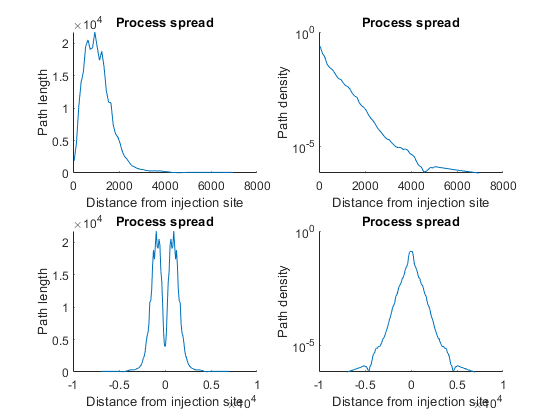

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal5009.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker{2}.point.Attributes, true);

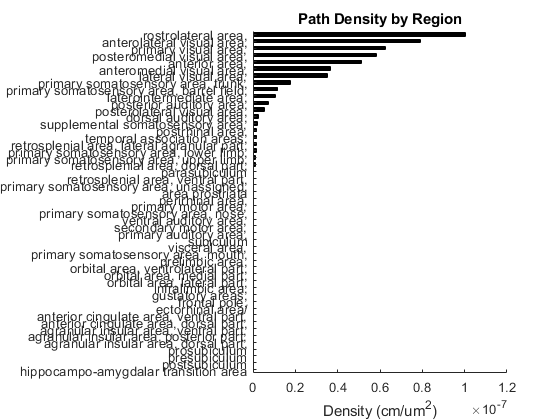

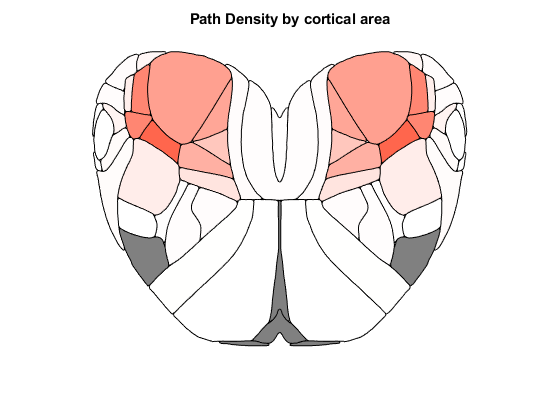

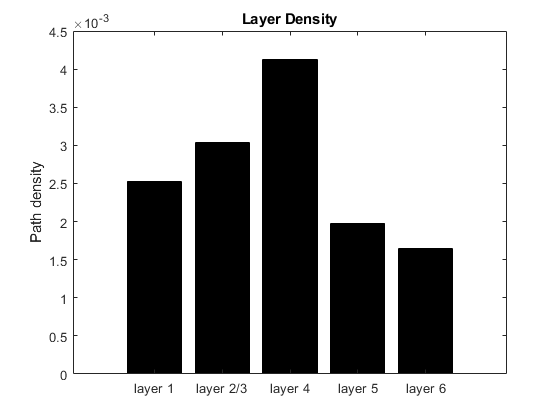

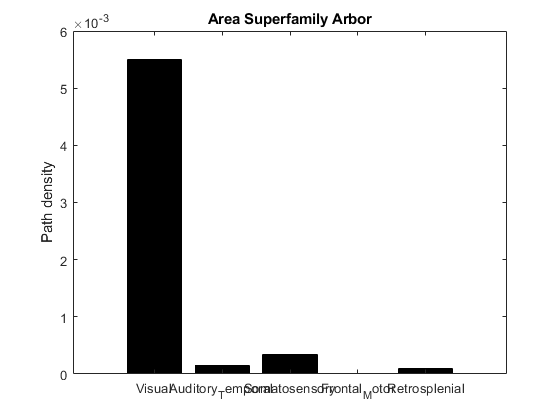

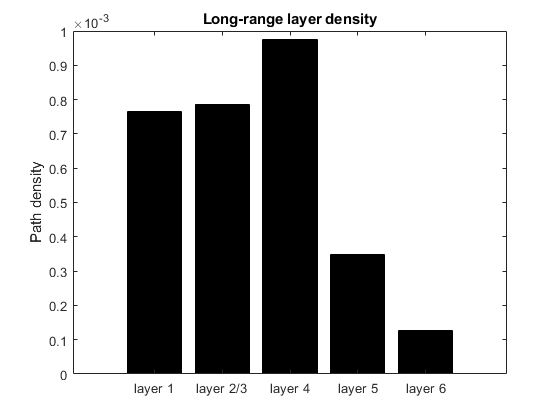


animal5009.tracingTables = buildTracingOutputTables(xmlData, xlTable, true, saveDir);


animal5009.somaCount = length(xmlData.mbf.marker{1}.point);

## Animal 5010

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_5010\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\5010';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'aligned_stack_plus_contours.xml'));
xlTable = readtable(fullfile(animalDir,'aligned_stack_plus_contours_contours_23_08_11.xlsx'));

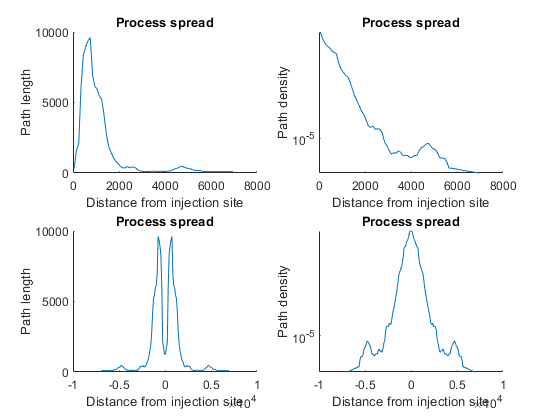

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal5010.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker{2}.point.Attributes, true);

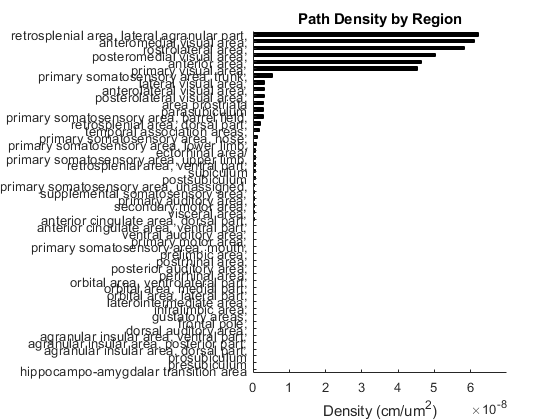

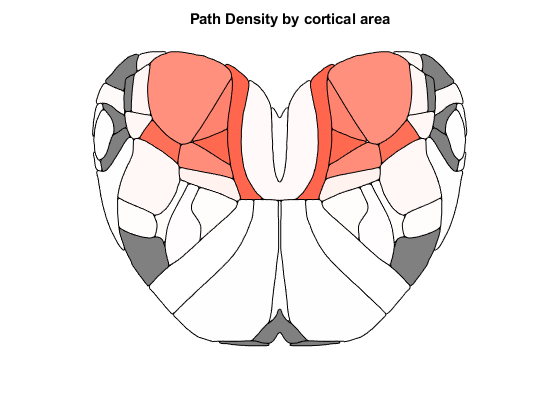

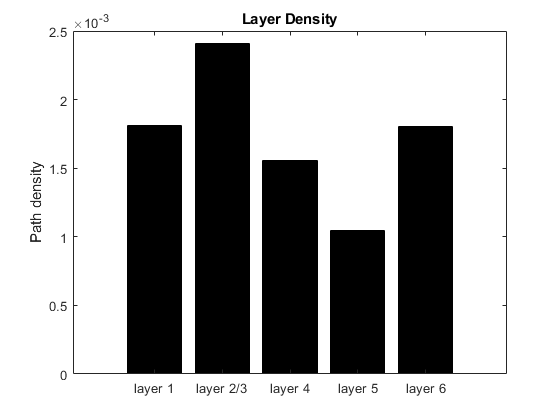

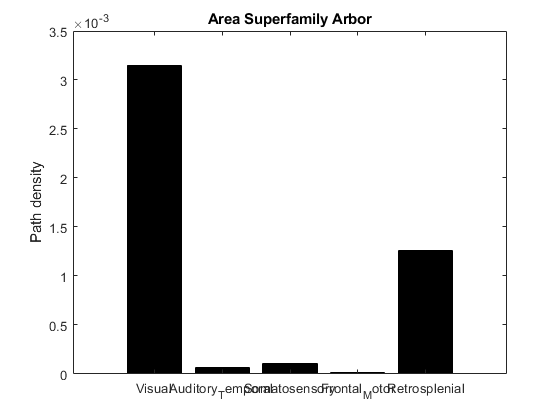

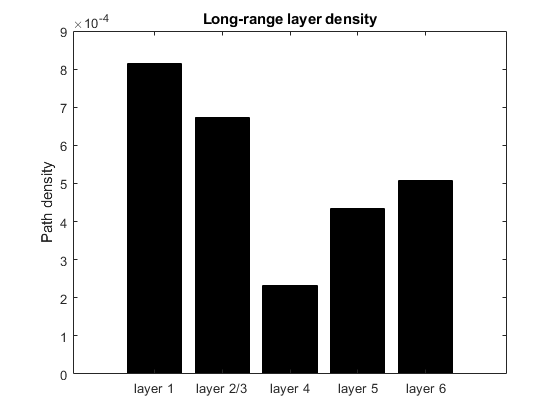


animal5010.tracingTables = buildTracingOutputTables(xmlData, xlTable, true, saveDir);


animal5010.somaCount = length(xmlData.mbf.marker{1}.point);

## Animal 5012

animalDir = 'W:\Jacob Ratliff\tracing_data\Animal_5012\data_files\aligned_stack';
saveDir = 'D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\Tracing_analysis\temp_data_files\5012';

% Load data from tracing and contours
xmlData = xml2struct(fullfile(animalDir,'animal_5012_aligned_stack_w_area_contours.xml'));
xlTable = readtable(fullfile(animalDir,'animal_5012_aligned_stack_w_area_contours_contours_23_08_11.xlsx'));

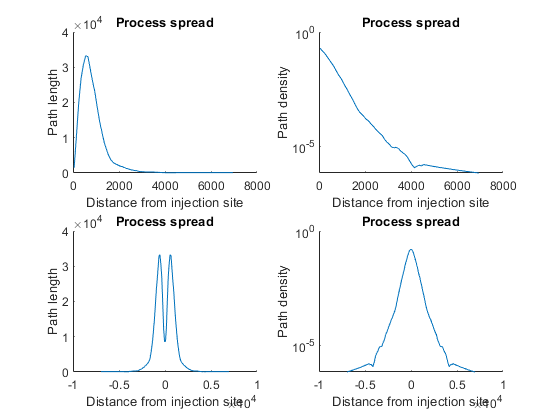

xlTable(end-3:end,:) = [];

% Analyze data and build output
animal5012.nodeDist = buildNodeDistribution(xmlData.mbf.tree, xmlData.mbf.marker.point.Attributes, true);

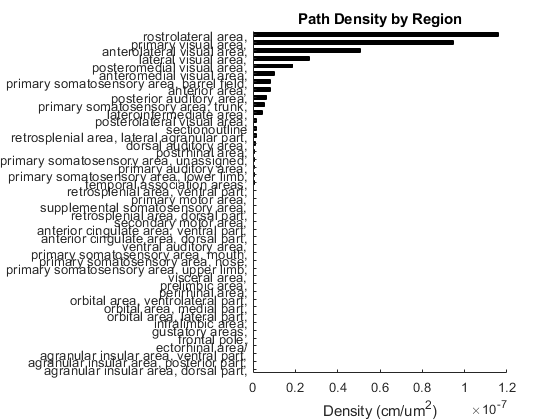

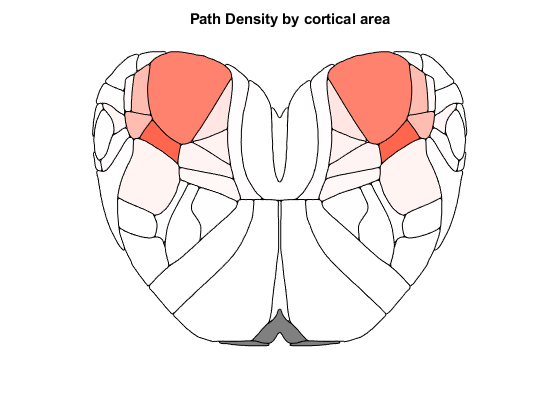

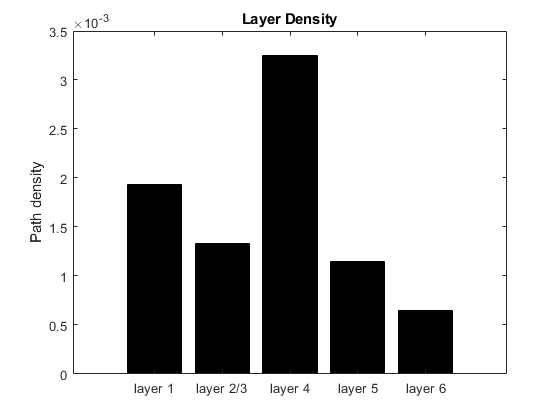

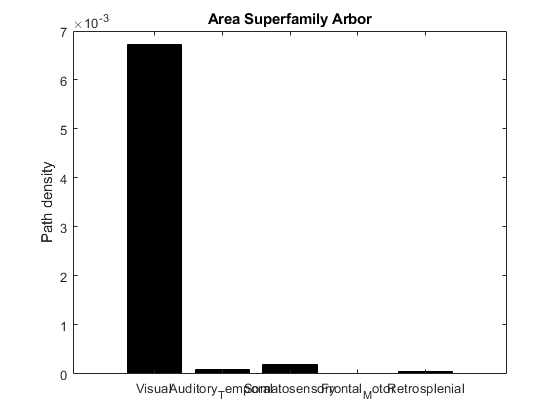

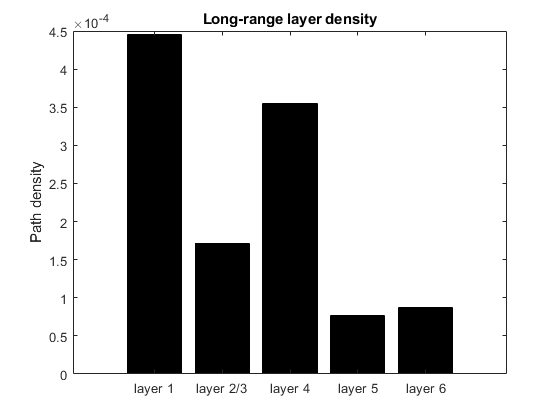


animal5012.tracingTables = buildTracingOutputTables(xmlData, xlTable, false, saveDir);


animal5012.somaCount = 38; % to be manually input

animals = [animal4619, animal5006, animal5008, animal5009, animal5010, animal5012];


Combine across animals

output = combineAcrossAnimals([animal4619, animal5006, animal5008, animal5009, animal5010, animal5012]);


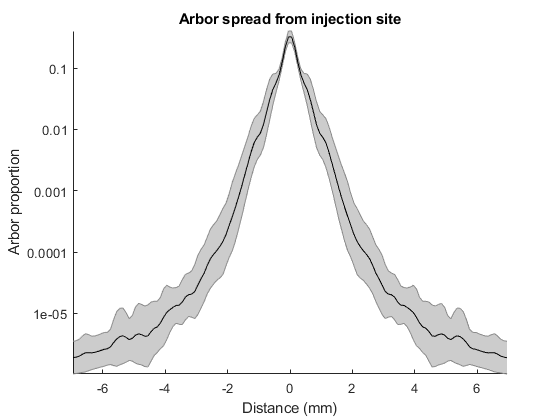

mirCenters = [-1*fliplr(animals(1).nodeDist.hist.binCenters)'; animals(1).nodeDist.hist.binCenters'];
mirMag = smoothdata([fliplr(output.nodeHist)'; output.nodeHist']./sum(output.nodeHist,2)',...
    1,'gaussian');

figure
shadedErrorBar(mirCenters/1000, mean(log10(mirMag),2), std(log10(mirMag),1,2))
yticks(-6:0)
yticklabels(10.^(-6:0))
ylabel('Arbor proportion')
xlabel('Distance (mm)')
title('Arbor spread from injection site')
axis tight

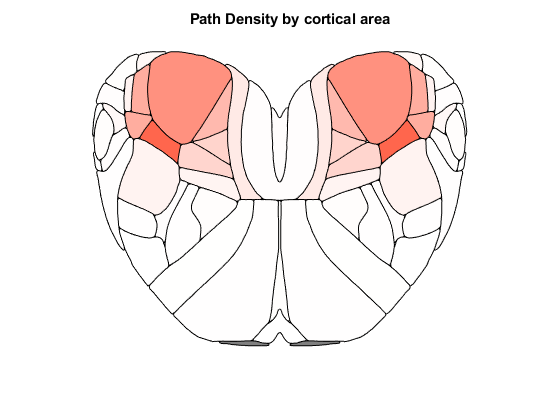

figure
plotTopDownBrain(output.AreaName, mean(output.areaDensity,1))
title('Path Density by cortical area')

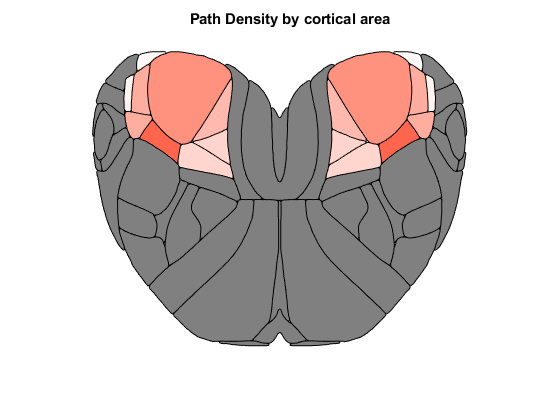

visualAreas = {'anterior area','anterolateral visual area',...
    'anteromedial visual area','lateral visual area',...
    'laterointermediate area','posterolateral visual area',...
    'posteromedial visual area','primary visual area',...
    'rostrolateral area'};
visMask = contains(lower(output.AreaName), visualAreas);

figure
plotTopDownBrain(output.AreaName(visMask), mean(output.areaDensity(:,visMask),1))
title('Path Density by cortical area')

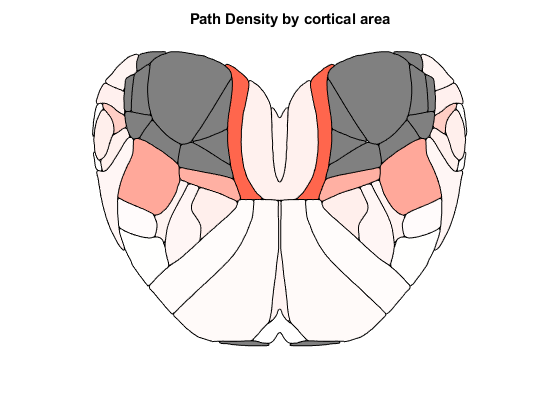


figure
plotTopDownBrain(output.AreaName(~visMask), mean(output.areaDensity(:,~visMask),1))
title('Path Density by cortical area')

% figure; subplot(1,2,1); hold on
% bar(1:5,mean(output.familyDensity,1),'FaceColor',[.5 .5 .5], 'LineStyle','none')
% errorbar(1:5, mean(output.familyDensity,1), std(output.familyDensity,0,1),...
%     'k','linestyle','none','LineWidth',2)
% xticks(1:5)
% xticklabels(output.familyName)
% xtickangle(45)
% ylabel('Projection density')
% 
% subplot(1,2,2); hold on
% bar(1:5,mean(output.familyDensity,1),'FaceColor',[.5 .5 .5], 'LineStyle','none')
% errorbar(1:5, mean(output.familyDensity,1), std(output.familyDensity,0,1),...
%     'k','linestyle','none','LineWidth',2)
% xticks(1:5)
% xticklabels(output.familyName)
% xtickangle(45)
% ylabel('Projection density')
% ylim([-.2 1]*10^-3)

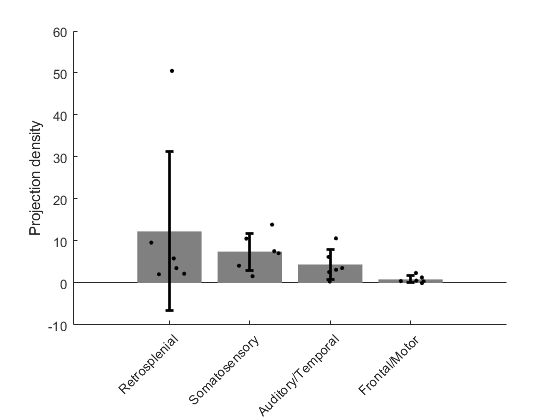

famOrder = [4,2,1,3]+1;
figure; hold on
bar(1:4,mean(output.familyDensity(:,famOrder),1),'FaceColor',[.5 .5 .5], 'LineStyle','none')
errorbar(1:4, mean(output.familyDensity(:,famOrder),1), std(output.familyDensity(:,famOrder),0,1),...
    'k','linestyle','none','LineWidth',2)
xticks(1:4)
xticklabels(output.familyName(famOrder))
xtickangle(45)
ylabel('Projection density')
scatter(reshape(repmat(1:4,[6 1]), 24, 1) + randn([24 1])*.1, reshape(output.familyDensity(:,famOrder), 24, 1),...
    10,'ko','filled')

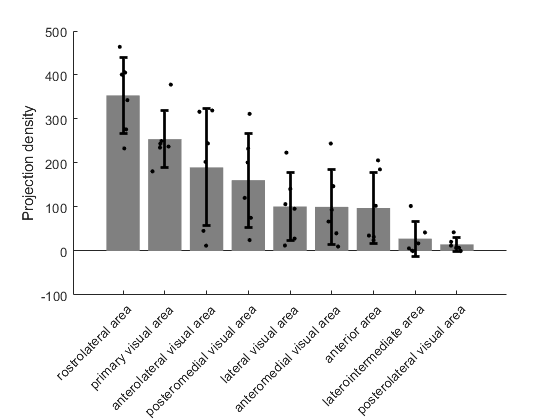


visualAreas = visualAreas([9,8,2,7,4,3,1,5,6]);

figure; hold on
for i = 1:length(visualAreas)
    areamask = strcmpi(output.AreaName, visualAreas(i) + ", ");  
    bar(i, mean(output.areaDensity(:,areamask)),...
        'FaceColor',[.5 .5 .5], 'LineStyle','none')
    errorbar(i, mean(output.areaDensity(:,areamask)), std(output.areaDensity(:,areamask)),...
        'k','linestyle','none','LineWidth',2)
    scatter(repmat(i,[6 1]) + randn([6 1])*.1, output.areaDensity(:,areamask),...
        10,'ko','filled')
end

xticks(1:length(visualAreas))
xticklabels(visualAreas)
xtickangle(45)
ylabel('Projection density')

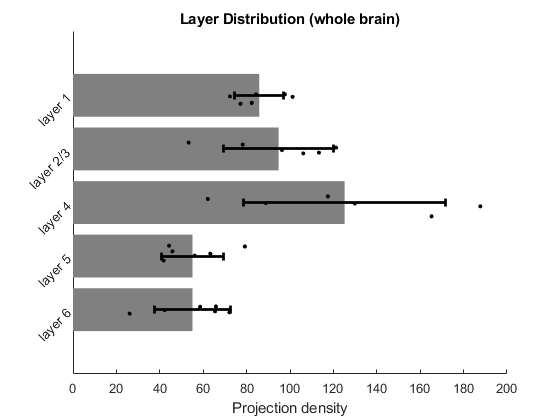

figure; hold on
barh(1:5, mean(output.layerDensity), 'FaceColor',[.5 .5 .5], 'LineStyle','none')
errorbar(mean(output.layerDensity,1), 1:5, std(output.layerDensity,0,1),...
    'horizontal','k','linestyle','none','LineWidth',2)
scatter(reshape(output.layerDensity, [], 1), reshape(repmat(1:5,[6 1]), [], 1) + randn([numel(output.layerDensity) 1])*.1, ...
    10,'ko','filled')
yticks(1:5)
yticklabels(output.layerNames)
ytickangle(45)
xlabel('Projection density')
set(gca,'ydir','reverse')
title('Layer Distribution (whole brain)')

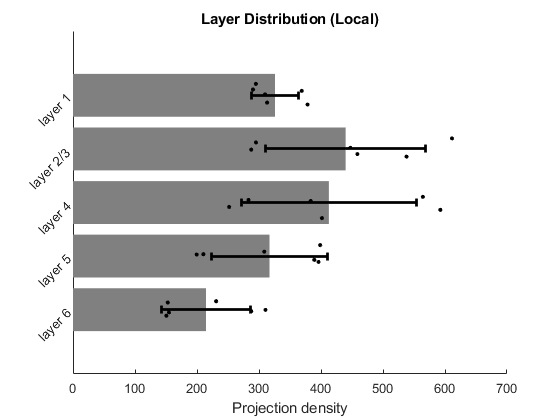

figure; hold on
barh(1:5, mean(output.visDensity), 'FaceColor',[.5 .5 .5], 'LineStyle','none')
errorbar(mean(output.visDensity,1), 1:5, std(output.visDensity,0,1),...
    'horizontal','k','linestyle','none','LineWidth',2)
scatter(reshape(output.visDensity, [], 1), reshape(repmat(1:5,[6 1]), [], 1) + randn([numel(output.visDensity) 1])*.1, ...
    10,'ko','filled')
yticks(1:5)
yticklabels(output.layerNames)
ytickangle(45)
xlabel('Projection density')
set(gca,'ydir','reverse')
title('Layer Distribution (Local)')

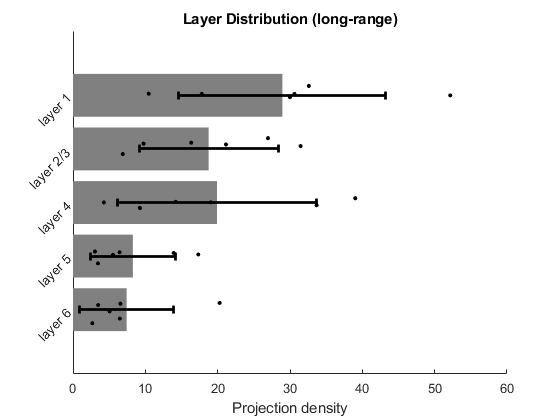

figure; hold on
barh(1:5, mean(output.longDensity), 'FaceColor',[.5 .5 .5], 'LineStyle','none')
errorbar(mean(output.longDensity,1), 1:5, std(output.longDensity,0,1),...
    'horizontal','k','linestyle','none','LineWidth',2)
scatter(reshape(output.longDensity, [], 1), reshape(repmat(1:5,[6 1]), [], 1) + randn([numel(output.longDensity) 1])*.1, ...
    10,'ko','filled')
yticks(1:5)
yticklabels(output.layerNames)
ytickangle(45)
xlabel('Projection density')
set(gca,'ydir','reverse')
title('Layer Distribution (long-range)')

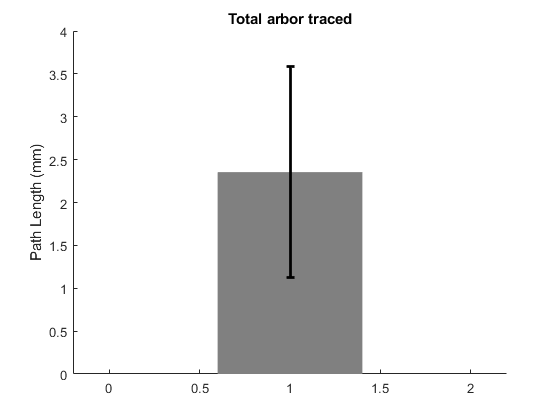

figure; hold on
bar(mean(output.totalLength/1000), 'FaceColor',[.5 .5 .5], 'LineStyle','none')
errorbar(mean(output.totalLength/1000), std(output.totalLength/1000),...
    'k','linestyle','none','LineWidth',2)
% xticks(1:5)
% xticklabels(output.layerNames)
% xtickangle(45)
ylabel('Path Length (mm)')
title('Total arbor traced')

figure; hold on
scatter(output.somaCount, output.totalLength/1000,'ko','filled')
xlim([0 max(xlim)])
ylim([0 max(ylim)])
xlabel('Somata labels')
ylabel('Total arbor traced (mm)')

mdl = fitlm(output.somaCount, output.totalLength/1000, 'linear','Intercept',false)

mdl = Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate       SE       tStat      pValue  
          ________    ________    ______    _________

    x1    0.099512    0.010446    9.5267    0.0002156


Number of observations: 6, Error degrees of freedom: 5
Root Mean Squared Error: 0.653

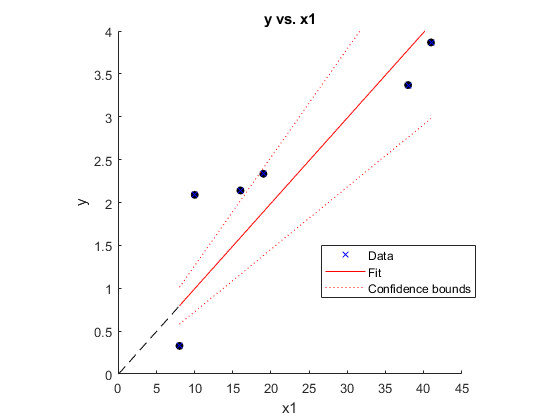

plot([0 45], [0 45]*mdl.Coefficients{1,1},'k--')
plot(mdl)
daspect manual

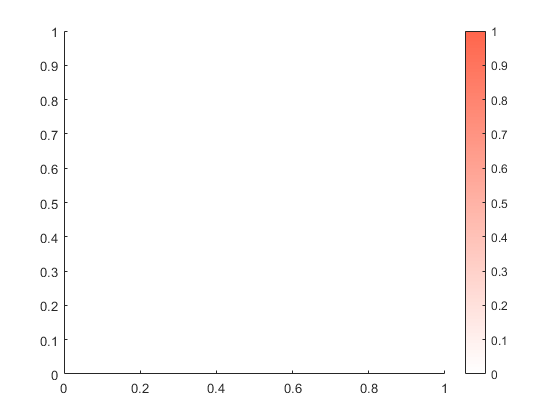

figure; colorbar
colormap(abs(1 - [0 .6 .7] .* linspace(0, 1, 100)'))

% Isocortex areas that don't have arbor detected
output.AreaName(mean(output.areaDensity) == 0)

ans = 9×1 cell array
    {'agranular insular area, dorsal part, '   }
    {'agranular insular area, posterior part, '}
    {'agranular insular area, ventral part, '  }
    {'frontal pole, '                          }
    {'gustatory areas, '                       }
    {'infralimbic area, '                      }
    {'orbital area, lateral part, '            }
    {'orbital area, medial part, '             }
    {'orbital area, ventrolateral part, '      }



% Average isocortex density
mean(output.totalDensity)

ans = 24.2497


% Approximate subiculum density (path_length/contour_area/section_thickness*unit_conversion_factor)
26/8195150/25*(1000^2)

ans = 0.1269

tbl = table(output.AreaName, mean(output.areaDensity)', std(output.areaDensity)',...
    'VariableNames',{'Area_Name', 'Area_density_mean', 'Area_density_std'});

[~, sortind] = sort(tbl.Area_density_mean,'descend');

tbl = tbl(sortind,:)

tbl = 43×3 table
                      Area_Name                       Area_density_mean    Area_density_std
    ______________________________________________    _________________    ________________

    'rostrolateral area, '                                 353.82               86.854     
    'primary visual area, '                                254.23               65.583     
    'anterolateral visual area, '                          190.11               132.86     
    'posteromedial visual area, '                          161.07               106.69     
    'lateral visual area, '                                101.27               77.217     
    'anteromedial visual area, '                           100.42                84.62     
    'anterior area, '                                      97.703               81.273     
    'retrosplenial area, lateral agranular part, '  


writetable(tbl,'D:\Dropbox (EinsteinMed)\Jacob\data and docs\Manuscripts\SST-nNOS-manuscript\tracingFig\supplement\AreaDensityTable.csv')

function output = combineAcrossAnimals(animals)

sharedAreas = intersect(animals(1).tracingTables.tables.area.AreaName, ...
    animals(end).tracingTables.tables.area.AreaName);

output.nodeHist = zeros(length(animals), length(animals(1).nodeDist.hist.binCenters));
output.areaDensity = [];
output.familyDensity = [];
output.layerDensity = [];
output.longDensity = [];
output.visDensity = [];
output.totalLength = [];

for i = 1:length(animals)
    output.nodeHist(i,:) = animals(i).nodeDist.hist.binMagnitude;
    
    tablemask = ismember(animals(i).tracingTables.tables.area.AreaName, sharedAreas);
    output.areaDensity(i,:) = animals(i).tracingTables.tables.area{tablemask,'PathLength'}./...
        animals(i).tracingTables.tables.area{tablemask,'AreaArea'};
    
    output.familyDensity(i,:) = animals(i).tracingTables.tables.superfamily.PathLength./...
        animals(i).tracingTables.tables.superfamily.Area;
    
    output.layerDensity(i,:) = animals(i).tracingTables.tables.layer.length ./ ...
        animals(i).tracingTables.tables.layer.area;
    
    output.longDensity(i,:) = animals(i).tracingTables.tables.nonvisualLayer.length ./ ...
        animals(i).tracingTables.tables.nonvisualLayer.area;
    
    output.visDensity(i,:) = animals(i).tracingTables.tables.visualLayer.length ./ ...
        animals(i).tracingTables.tables.visualLayer.area;
    
    output.totalDensity(i) = sum(animals(i).tracingTables.tables.area{tablemask,'PathLength'})/...
        sum(animals(i).tracingTables.tables.area{tablemask,'AreaArea'});
    
    totalLengthDistance = sum([animals(i).nodeDist.nodeDistribution{:}]);
    output.totalLength(i) = totalLengthDistance(1);
end

output.somaCount = [animals.somaCount];

output.AreaName = sharedAreas;
output.familyName = {'Visual', 'Auditory/Temporal', ...
    'Somatosensory', 'Frontal/Motor', 'Retrosplenial'};
output.layerNames = animals(1).tracingTables.tables.layer.name;

% Output in correct units
SectionThicknessCorrection = 25; % microns thick section
um_per_cbum_to_mm_per_cb_mm = 1000^3/1000;

output.areaDensity = output.areaDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
output.familyDensity = output.familyDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
output.layerDensity = output.layerDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
output.longDensity = output.longDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
output.visDensity = output.visDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
output.totalDensity = output.totalDensity / SectionThicknessCorrection * um_per_cbum_to_mm_per_cb_mm;
end